# 4(a) 冲激响应不变法设计Butterworth数字滤波器

## （1）Butterworth数字高通滤波器：

clear all;
close all;
fs=300;
fp=200;
Fs=1000;
Rp=3;  Rs=30;

wp=2*pi*fp/Fs;
ws=2*pi*fs/Fs;

OmegaP=2*Fs*tan(wp/2);
OmegaS=2*Fs*tan(ws/2);

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 

Bp =      0     0     0     0     0     0     1


Ap =     1.0000    3.8637    7.4641    9.1416    7.4641    3.8637    1.0000


[b,a]=lp2lp(Bp,Ap,Wn)       %模拟低通滤波器到模拟高通滤波器的转换 

b = 1.3767e+19

a = 	1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0034    1.3767


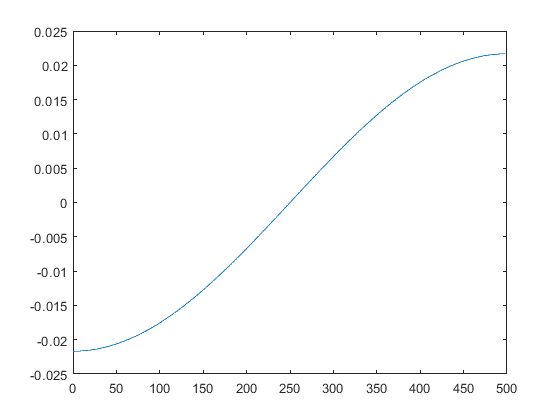

figure(1); 
[h,w]=freqz(b,a,256,Fs);
plot(w,20*log10(abs(h)))

## （2）Butterworth数字低通滤波器：

clear all;
close all;
fp=200;
fs=300;
Fs=1000;
Rp=3;  Rs=30;

wp=2*pi*fp/Fs;
ws=2*pi*fs/Fs;

OmegaP=2*Fs*tan(wp/2);
OmegaS=2*Fs*tan(ws/2);

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 

Bp =      0     0     0     0     0     0     1


Ap =     1.0000    3.8637    7.4641    9.1416    7.4641    3.8637    1.0000


[b,a]=lp2hp(Bp,Ap,Wn)       %模拟低通滤波器到模拟高通滤波器的转换 

b = 	1.0e+03 *

    0.0010    0.0000    0.0000    0.0000    0.0000    0.0104    4.0439


a = 	1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0034    1.3767


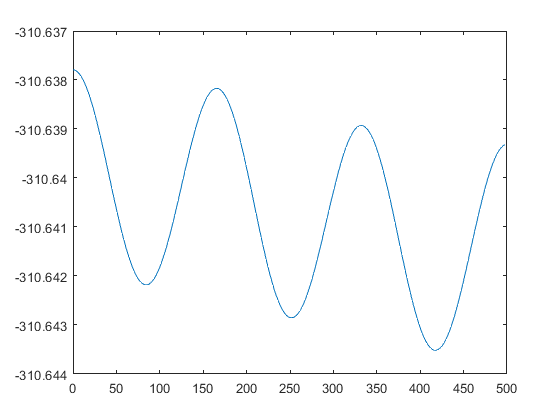

figure(1); 
[h,w]=freqz(b,a,256,Fs);
plot(w,20*log10(abs(h)))

## （3）Butterworth数字带通滤波器：

clear all;
close all;
fp=[270 330];fs=[200 400];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
Rp=3;Rs=30;

wp=2.*pi.*fp./Fs;
ws=2.*pi.*fs./Fs;

OmegaP=2*Fs*tan(wp./2);
OmegaS=2*Fs*tan(ws./2);
bw=OmegaP(2)-OmegaP(1)
w0=sqrt(OmegaP(1)*OmegaP(2))

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 
[b,a]=lp2bp(Bp,Ap,Wn,bw)       %模拟低通滤波器到模拟高通滤波器的转换 
figure(1); 
[h,w]=freqz(b,a,256,Fs);
plot(w,20*log10(abs(h)))

## （4）Butterworth数字带阻滤波器：

clear all;
close all;
fp=[270 330];fs=[200 400];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
Rp=3;Rs=30;

wp=2.*pi.*fp./Fs;
ws=2.*pi.*fs./Fs;

OmegaP=2*Fs*tan(wp./2);
OmegaS=2*Fs*tan(ws./2);
bw=OmegaP(2)-OmegaP(1)
w0=sqrt(OmegaP(1)*OmegaP(2))

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 
[b,a]=lp2bs(Bp,Ap,Wn,bw)       %模拟低通滤波器到模拟高通滤波器的转换 
figure(1); 
[h,w]=freqz(b,a,256,Fs);
plot(w,20*log10(abs(h)))